infected = [1,2,4,5,7,8,9,10,11,13,14,20,24,27,30,34,47,54,60,67,78,96,117,157,196,250,324,425,569,690,846,1055,1281,1429,2061,2778,3385,4018,4743,5652];
population = 37590000;
s0 = population - infected(1);
i0 = infected(1);

params = fmincon(@(x)numeric_sol_err(x, infected, population), [0.5, 0.5], [], [], [], [], [0 0], [1 1]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



R0 = params(1)/params(2) %R0 = beta/gamma

R0 = 1.3332

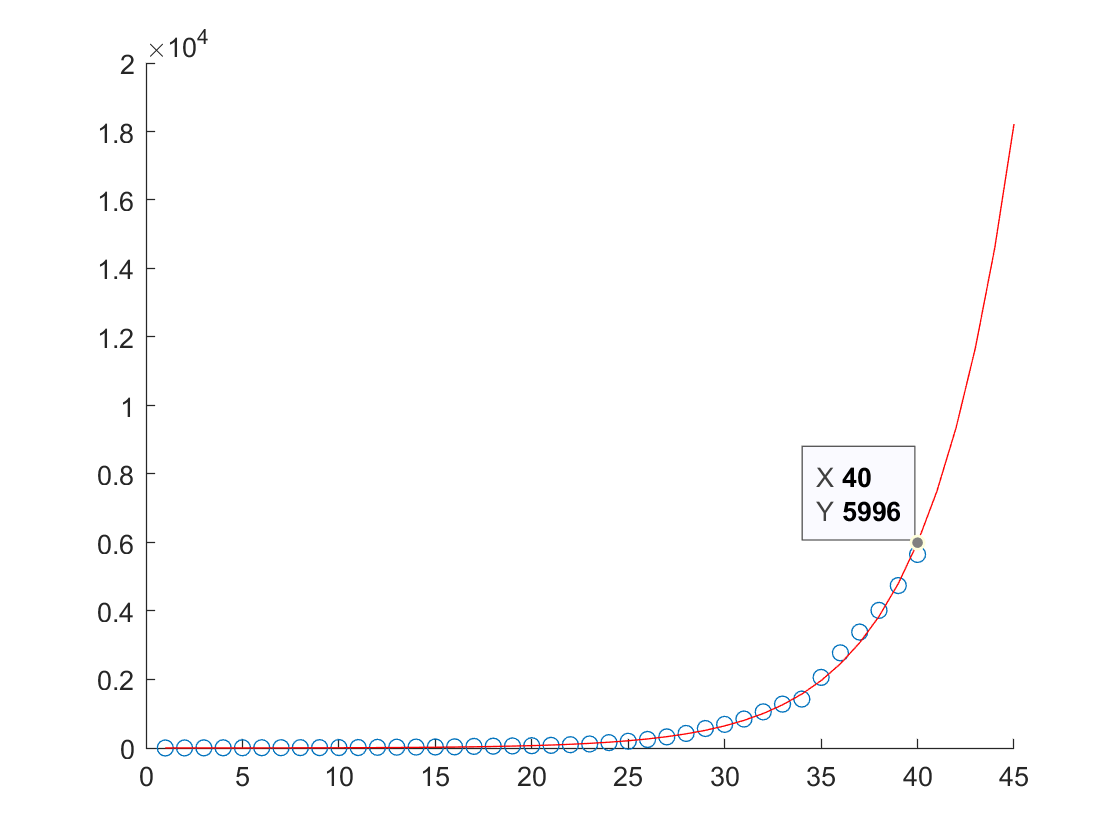

sols = numeric_sol(s0, i0, params(1), params(2), population, 1, 45);
%error = numeric_sol_err(params, infected, population)
figure
scatter(1:length(infected), infected);
hold on
plot(1:length(sols), sols(2, :), 'r');
hold on

function sols = numeric_sol(s0, i0, b, g, population, delta_t, steps)
    sols = zeros(2, steps);
    sols(1, 1) = s0;
    sols(2, 1) = i0;
    
    for x = 2:steps
        s = sols(1, x-1);
        i = sols(2, x-1);
        sols(1, x) = sols(1, x-1) - delta_t*b*i*s/population;
        sols(2, x) = sols(2, x-1) + delta_t*((b*i*s)/population-g*i);
    end
end

function error = numeric_sol_err(params, infected, population)
    sols = numeric_sol(population-infected(1), infected(1), params(1), params(2), population, 1, length(infected));
    error = sum((infected - sols(2, :)).^2, 'all');
end
